% %% 简洁高效的NLMS与Kalman组合降噪系统
% clear; clc; close all;
% 
% % 加载数据
% load('Hw2a.mat');
% s_in = Sin_a;       % 含噪信号 [N x 2]
% s_ref = Sn_ref_a;   % 参考噪声 [N x 2]
% 
% 
% % 信号归一化
% s_in = s_in / max(abs(s_in(:)));
% s_ref = s_ref / max(abs(s_ref(:)));
% [N, num_ch] = size(s_in);
% 
% %% ================ NLMS降噪 ================
% % 参数设置
% L_nlms = 512;       % 滤波器阶数
% mu = 0.005;          % 步长
% delta = 1e-6;       % 正则化常数
% 
% % 初始化输出
% s_nlms = zeros(N, num_ch);
% 
% % 对每个声道独立处理
% for ch = 1:num_ch
%     w = zeros(L_nlms, 1);  % 滤波器权重
% 
%     for n = L_nlms:N
%         % 提取参考噪声向量
%         x = s_ref(n:-1:n-L_nlms+1, ch);
% 
%         % 估计噪声
%         noise_est = w' * x;
% 
%         % 计算误差（即初步降噪信号）
%         e = s_in(n, ch) - noise_est;
%         s_nlms(n, ch) = e;
% 
%         % 权重更新
%         w = w + (mu * e * x) / (x' * x + delta);
%     end
% end
% 
% %% ================ Kalman后处理 ================
% % 参数设置
% Q = 1e-5;    % 过程噪声协方差
% R = 0.01;     % 观测噪声协方差
% 
% % 初始化输出
% s_kalman = zeros(N, num_ch);
% 
% % Kalman滤波器状态
% x_hat = 0;   % 状态估计（纯净信号）
% P = 1;       % 误差协方差
% 
% % 对每个声道独立处理
% for ch = 1:num_ch
%     % 重置Kalman状态
%     x_hat = 0;
%     P = 1;
% 
%     for n = 1:N
%         % 预测步骤
%         x_hat_minus = x_hat;     % 状态预测
%         P_minus = P + Q;         % 协方差预测
% 
%         % 更新步骤
%         z = s_nlms(n, ch);       % 观测值（NLMS的输出）
%         K = P_minus / (P_minus + R); % Kalman增益
%         x_hat = x_hat_minus + K * (z - x_hat_minus); % 状态更新
%         P = (1 - K) * P_minus;   % 协方差更新
% 
%         % 存储结果
%         s_kalman(n, ch) = x_hat;
%     end
% end
% 
% % 归一化输出
% s_kalman = s_kalman / max(abs(s_kalman(:)));
% 
% %% ================ 结果评估 ================
% % 时域波形对比
% t = (0:N-1)/fs;
% figure;
% subplot(3,1,1);
% plot(t, s_in(:,1)); title('原始含噪信号');
% xlabel('时间 (s)'); ylabel('幅度');
% xlim([0, min(5, N/fs)]); % 显示前5秒
% 
% subplot(3,1,2);
% plot(t, s_nlms(:,1)); title('NLMS降噪结果');
% xlabel('时间 (s)'); ylabel('幅度');
% xlim([0, min(5, N/fs)]);
% 
% subplot(3,1,3);
% plot(t, s_kalman(:,1)); title('Kalman后处理结果');
% xlabel('时间 (s)'); ylabel('幅度');
% xlim([0, min(5, N/fs)]);
% 
% % 频谱对比
% figure;
% freq_range = [80, 5000]; % 吉他主要频率范围
% 
% % 计算频谱
% [P_in, f] = pwelch(s_in(:,1), 2048, 1024, 2048, fs);
% [P_nlms, ~] = pwelch(s_nlms(:,1), 2048, 1024, 2048, fs);
% [P_kalman, ~] = pwelch(s_kalman(:,1), 2048, 1024, 2048, fs);
% 
% % 绘制频谱
% semilogx(f, 10*log10(P_in), 'b', 'LineWidth', 1.5); hold on;
% semilogx(f, 10*log10(P_nlms), 'g', 'LineWidth', 1.5);
% semilogx(f, 10*log10(P_kalman), 'r', 'LineWidth', 1.5); hold off;
% 
% title('频谱对比 (左声道)');
% xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
% legend('原始', 'NLMS', 'Kalman后处理');
% xlim(freq_range); grid on;
% 
% % disp('播放NLMS降噪信号...');
% % sound(s_nlms, fs);
% % pause(N/fs + 1);
% 
% disp('播放Kalman后处理信号...');
% sound(s_kalman, fs);
% 
% % 保存结果
% audiowrite('original.wav', s_in, fs);
% audiowrite('nlms_denoised.wav', s_nlms, fs);
% audiowrite('kalman_denoised.wav', s_kalman, fs);
% disp('音频文件已保存');
% 
% 
% 
% 




% 
% %% GOOD! filter in the after NLMS
% %% Full Signal Processing and Analysis System
% clear; clc; close all;
% 
% % Load data
% load('Hw2a.mat');
% s_in = Sin_a;       % Noisy signal [N x 2]
% s_ref = Sn_ref_a;   % Reference noise [N x 2]
% 
% % load('Hw2b.mat');
% % s_in = Sin_b;       % Noisy signal [N x 2]
% % s_ref = Sn_ref_b;   % Reference noise [N x 2]
% 
% % Normalize signals
% s_in = s_in / max(abs(s_in(:)));
% s_ref = s_ref / max(abs(s_ref(:)));
% [N, num_ch] = size(s_in);
% 
% % Calculate total duration
% total_duration = N / fs;
% fprintf('Total signal duration: %.2f seconds\n', total_duration);
% 
% %% ================ NLMS Denoising ================
% L_nlms = 64;       
% mu = 0.02;         
% delta = 1e-6;      
% 
% s_nlms = zeros(N, num_ch);
% 
% fprintf('Starting NLMS denoising...\n');
% start_time = tic;
% 
% for ch = 1:num_ch
%     w = zeros(L_nlms, 1);  
%     error_signal = zeros(N, 1); 
% 
%     for n = L_nlms:N
%         x = s_ref(n:-1:n-L_nlms+1, ch);
%         noise_est = w' * x;
%         e = s_in(n, ch) - noise_est;
%         s_nlms(n, ch) = e;
%         error_signal(n) = e;
%         w = w + (mu * e * x) / (x' * x + delta);
%     end
% 
%     fprintf('Channel %d NLMS done. Avg error: %.4f\n', ch, mean(abs(error_signal(L_nlms:end))));
% end
% 
% nlms_time = toc(start_time);
% fprintf('NLMS completed in %.2f seconds.\n', nlms_time);
% 
% %% ================ Kalman Post-Processing ================
% Q = 5e-7;    
% R = 0.1;    
% 
% s_kalman = zeros(N, num_ch);
% 
% fprintf('Starting Kalman post-processing...\n');
% start_time = tic;
% 
% for ch = 1:num_ch
%     x_hat = 0;
%     P = 1;
% 
%     for n = 1:N
%         x_hat_minus = x_hat;
%         P_minus = P + Q;
%         z = s_nlms(n, ch);
%         K = P_minus / (P_minus + R);
%         x_hat = x_hat_minus + K * (z - x_hat_minus);
%         P = (1 - K) * P_minus;
%         s_kalman(n, ch) = x_hat;
%     end
% 
%     fprintf('Channel %d Kalman done.\n', ch);
% end
% 
% kalman_time = toc(start_time);
% fprintf('Kalman completed in %.2f seconds.\n', kalman_time);
% 
% %% ================ Guitar Band Protection ================
% f_low = 300;    
% f_high = 5000;  
% order = 6;     
% 
% [b_bp, a_bp] = butter(order, [f_low, f_high]/(fs/2), 'bandpass');
% 
% s_nlms_bp = zeros(size(s_nlms));
% s_kalman_bp = zeros(size(s_kalman));
% 
% for ch = 1:num_ch
%     s_nlms_bp(:, ch) = filtfilt(b_bp, a_bp, s_nlms(:, ch));
%     s_kalman_bp(:, ch) = filtfilt(b_bp, a_bp, s_kalman(:, ch));
% end
% 
% s_nlms_bp = s_nlms_bp / max(abs(s_nlms_bp(:)));
% s_kalman_bp = s_kalman_bp / max(abs(s_kalman_bp(:)));
% 
% %% ================ Full Signal Analysis ================
% noise_original = s_ref;
% noise_nlms = s_in - s_nlms_bp;
% noise_kalman = s_in - s_kalman_bp;
% 
% noise_energy_orig = mean(noise_original.^2);
% noise_energy_nlms = mean(noise_nlms.^2);
% noise_energy_kalman = mean(noise_kalman.^2);
% 
% fprintf('\nNoise Energy Analysis:\n');
% fprintf('Original noise energy: %.4f (L), %.4f (R)\n', noise_energy_orig(1), noise_energy_orig(2));
% fprintf('After NLMS: %.4f (L), %.4f (R)\n', noise_energy_nlms(1), noise_energy_nlms(2));
% fprintf('After Kalman: %.4f (L), %.4f (R)\n', noise_energy_kalman(1), noise_energy_kalman(2));
% 
% signal_energy = mean(s_in.^2);
% snr_orig = 10*log10(signal_energy ./ noise_energy_orig);
% snr_nlms = 10*log10(signal_energy ./ noise_energy_nlms);
% snr_kalman = 10*log10(signal_energy ./ noise_energy_kalman);
% 
% fprintf('\nSNR Analysis:\n');
% fprintf('Original SNR: %.2f dB (L), %.2f dB (R)\n', snr_orig(1), snr_orig(2));
% fprintf('After NLMS: %.2f dB (L), %.2f dB (R)\n', snr_nlms(1), snr_nlms(2));
% fprintf('After Kalman: %.2f dB (L), %.2f dB (R)\n', snr_kalman(1), snr_kalman(2));
% 
% %% ================ Visualization ================
% figure('Name', 'Time-Domain Comparison', 'Position', [100, 100, 1400, 800]);
% 
% t = (0:N-1)/fs;
% display_range = 1:min(10*fs, N);
% 
% subplot(3,1,1);
% plot(t(display_range), s_in(display_range,1)); 
% title('Original Noisy Signal (First 10s)');
% xlabel('Time (s)'); ylabel('Amplitude');
% 
% subplot(3,1,2);
% plot(t(display_range), s_nlms_bp(display_range,1)); 
% title('NLMS Denoised Output (First 10s)');
% xlabel('Time (s)'); ylabel('Amplitude');
% 
% subplot(3,1,3);
% plot(t(display_range), s_kalman_bp(display_range,1)); 
% title('Kalman Output (First 10s)');
% xlabel('Time (s)'); ylabel('Amplitude');
% 
% %% Spectrum Comparison
% figure('Name', 'Full Spectrum Analysis', 'Position', [100, 100, 1200, 500]);
% 
% [P_in, f] = pwelch(s_in(:,1), 4096, 2048, 4096, fs);
% [P_nlms, ~] = pwelch(s_nlms_bp(:,1), 4096, 2048, 4096, fs);
% [P_kalman, ~] = pwelch(s_kalman_bp(:,1), 4096, 2048, 4096, fs);
% 
% subplot(1,2,1);
% semilogx(f, 10*log10(P_in), 'b', 'LineWidth', 1.5); hold on;
% semilogx(f, 10*log10(P_nlms), 'g', 'LineWidth', 1.5);
% semilogx(f, 10*log10(P_kalman), 'r', 'LineWidth', 1.5); hold off;
% title('Spectrum Comparison (Full Range)');
% xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
% legend('Original', 'NLMS', 'Kalman');
% xlim([20, 20000]); grid on;
% 
% subplot(1,2,2);
% plot(f, 10*log10(P_in), 'b', 'LineWidth', 1.5); hold on;
% plot(f, 10*log10(P_nlms), 'g', 'LineWidth', 1.5);
% plot(f, 10*log10(P_kalman), 'r', 'LineWidth', 1.5); hold off;
% title('Guitar Frequency Band (100–4800 Hz)');
% xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
% xlim([80, 5000]); grid on;
% yl = ylim;
% rectangle('Position', [f_low, yl(1), f_high-f_low, yl(2)-yl(1)], ...
%           'EdgeColor', 'k', 'LineStyle', '--', 'FaceColor', 'none');
% text(150, yl(2)-5, 'Guitar Band', 'FontSize', 12, 'Color', 'k');
% 
% %% ================ Playback UI ================
% f_ui = figure('Name', 'Audio Playback Control', 'Position', [200, 200, 900, 100]);
% 
% button_width = 200;
% button_height = 40;
% button_spacing = 20;
% start_x = 40;
% 
% uicontrol('Style', 'pushbutton', 'String', 'Play Original Audio', ...
%     'Position', [start_x, 30, button_width, button_height], ...
%     'Callback', @(src,evt) sound(s_in, fs));
% 
% uicontrol('Style', 'pushbutton', 'String', 'Play NLMS Output', ...
%     'Position', [start_x + (button_width + button_spacing), 30, button_width, button_height], ...
%     'Callback', @(src,evt) sound(s_nlms_bp, fs));
% 
% uicontrol('Style', 'pushbutton', 'String', 'Play Kalman Output', ...
%     'Position', [start_x + 2*(button_width + button_spacing), 30, button_width, button_height], ...
%     'Callback', @(src,evt) sound(s_kalman_bp, fs));
% 
% uicontrol('Style', 'pushbutton', 'String', 'Pause Playback', ...
%     'Position', [start_x + 3*(button_width + button_spacing), 30, button_width, button_height], ...
%     'Callback', 'clear sound');
% 
% %% ================ Save Results ================
% audiowrite('original_full.wav', s_in, fs);
% audiowrite('nlms_denoised_full.wav', s_nlms_bp, fs);
% audiowrite('kalman_denoised_full.wav', s_kalman_bp, fs);
% fprintf('\nAudio files saved:\n');
% fprintf('  - original_full.wav\n');
% fprintf('  - nlms_denoised_full.wav\n');
% fprintf('  - kalman_denoised_full.wav\n');
% 
% save('denoising_results.mat', 's_in', 's_ref', 's_nlms_bp', 's_kalman_bp', 'fs');
% fprintf('Data saved: denoising_results.mat\n');
% disp('Processing complete. Use the playback interface to listen.');
% 





%% %% GoooooD
%% Final Version: Filter-before-NLMS/Kalman with Full Playback and Visualization
clear; clc; close all;

%% Load Data
load('Hw2a.mat');
s_in = Sin_a;       
s_ref = Sn_ref_a;   


lag_correction = 1;
s_ref = [s_ref(lag_correction+1:end, :); zeros(lag_correction, size(s_ref,2))];

% Normalize
s_in = s_in / max(abs(s_in(:)));
s_ref = s_ref / max(abs(s_ref(:)));
[N, num_ch] = size(s_in);
fprintf('Total Duration: %.2f seconds\n', N/fs);

Total Duration: 74.01 seconds



%% Pre-filtering (Bandpass before processing)
f_low = 100;    
f_high = 5000;  
order = 6;      
[b_bp, a_bp] = butter(order, [f_low, f_high]/(fs/2), 'bandpass');

for ch = 1:num_ch
    s_in(:, ch) = filtfilt(b_bp, a_bp, s_in(:, ch));
    s_ref(:, ch) = filtfilt(b_bp, a_bp, s_ref(:, ch));
end

%% NLMS Denoising
L_nlms = 64;       
mu = 0.02;         
delta = 1e-6;      
s_nlms = zeros(N, num_ch);
fprintf('\nStarting NLMS denoising...\n');


Starting NLMS denoising...


tic;

for ch = 1:num_ch
    w = zeros(L_nlms, 1);  
    for n = L_nlms:N
        x = s_ref(n:-1:n-L_nlms+1, ch);
        d = s_in(n, ch);
        y = w' * x;
        e = d - y;
        s_nlms(n, ch) = e;
        w = w + (mu * e * x) / (x' * x + delta);
    end
end

fprintf('NLMS completed in %.2f seconds.\n', toc);

NLMS completed in 0.97 seconds.



%% Kalman Post-Processing
Q = 10e-6;    
R = 0.01;    
s_kalman = zeros(N, num_ch);
fprintf('Starting Kalman post-processing...\n');

Starting Kalman post-processing...


tic;

for ch = 1:num_ch
    x_hat = 0;
    P = 1;
    for n = 1:N
        x_hat_minus = x_hat;
        P_minus = P + Q;
        K = P_minus / (P_minus + R);
        x_hat = x_hat_minus + K * (s_nlms(n, ch) - x_hat_minus);
        P = (1 - K) * P_minus;
        s_kalman(n, ch) = x_hat;
    end
end

fprintf('Kalman completed in %.2f seconds.\n', toc);

Kalman completed in 0.02 seconds.



%% Normalize Final Outputs
s_nlms = s_nlms / max(abs(s_nlms(:)));
s_kalman = s_kalman / max(abs(s_kalman(:)));

%% Noise/SNR Analysis
noise_nlms = s_in - s_nlms;
noise_kalman = s_in - s_kalman;
noise_energy_orig = mean(s_ref.^2);
noise_energy_nlms = mean(noise_nlms.^2);
noise_energy_kalman = mean(noise_kalman.^2);
signal_energy = mean(s_in.^2);
snr_orig = 10*log10(signal_energy ./ noise_energy_orig);
snr_nlms = 10*log10(signal_energy ./ noise_energy_nlms);
snr_kalman = 10*log10(signal_energy ./ noise_energy_kalman);

fprintf('\nNoise Energy (L/R):  Orig: %.4f / %.4f | NLMS: %.4f / %.4f | Kalman: %.4f / %.4f\n', ...
    noise_energy_orig(1), noise_energy_orig(2), noise_energy_nlms(1), noise_energy_nlms(2), noise_energy_kalman(1), noise_energy_kalman(2));


Noise Energy (L/R):  Orig: 0.0130 / 0.0125 | NLMS: 0.0118 / 0.0132 | Kalman: 0.0189 / 0.0287


fprintf('SNR (dB):            Orig: %.2f / %.2f | NLMS: %.2f / %.2f | Kalman: %.2f / %.2f\n', ...
    snr_orig(1), snr_orig(2), snr_nlms(1), snr_nlms(2), snr_kalman(1), snr_kalman(2));

SNR (dB):            Orig: 0.25 / 1.06 | NLMS: 0.67 / 0.83 | Kalman: -1.36 / -2.55


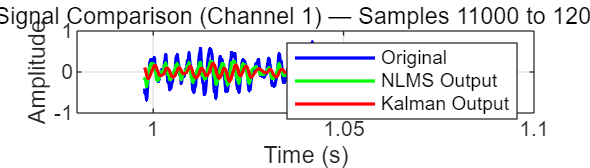


%% Visualization (Zoomed Signal Comparison: Samples 11000–12000)
start_idx = 11000;
end_idx = 12000;
t_zoom = (start_idx:end_idx) / fs;

figure('Name', 'Zoomed Time-Domain Comparison (11000–12000)', 'Position', [100, 100, 1400, 400]);
plot(t_zoom, Sin_a(start_idx:end_idx,1), 'b', 'LineWidth', 1.2); hold on;
plot(t_zoom, s_nlms(start_idx:end_idx,1), 'g', 'LineWidth', 1.2);
plot(t_zoom, s_kalman(start_idx:end_idx,1), 'r', 'LineWidth', 1.2); hold off;
xlabel('Time (s)');
ylabel('Amplitude');
title('Signal Comparison (Channel 1) — Samples 11000 to 12000');
legend('Original', 'NLMS Output', 'Kalman Output');
grid on;

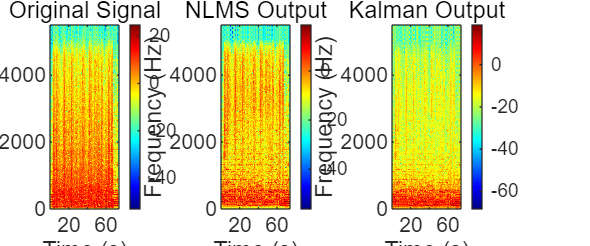



%% Time-Frequency Spectrograms (Centered, Clean Layout)
window_length = 1024;
overlap = round(0.75 * window_length);
nfft = 2048;

% Compute Spectrograms
[S1,F1,T1] = spectrogram(Sin_a(:,1), window_length, overlap, nfft, fs);
[S2,F2,T2] = spectrogram(s_nlms(:,1), window_length, overlap, nfft, fs);
[S3,F3,T3] = spectrogram(s_kalman(:,1), window_length, overlap, nfft, fs);

% Create a blank figure
figure('Name', 'Time-Frequency Spectrograms (Channel 1)', 'Position', [100, 100, 1600, 600], 'Color', 'w');

% Axes dimensions (manually controlled for centered layout)
w = 0.25;         % width of each axes
h = 0.75;         % height of each axes
y = 0.15;         % bottom margin
gap = 0.04;       % gap between axes
start_x = (1 - (3*w + 2*gap)) / 2;  % center all three axes

% ---- Plot 1: Original ----
ax1 = axes('Position', [start_x, y, w, h]);
imagesc(T1, F1, 10*log10(abs(S1) + 1e-12)); axis xy;
colormap jet; colorbar;
title('Original Signal');
xlabel('Time (s)'); ylabel('Frequency (Hz)');
ylim([0, 5500]);

% ---- Plot 2: NLMS ----
ax2 = axes('Position', [start_x + w + gap, y, w, h]);
imagesc(T2, F2, 10*log10(abs(S2) + 1e-12)); axis xy;
colormap jet; colorbar;
title('NLMS Output');
xlabel('Time (s)'); ylabel('Frequency (Hz)');
ylim([0, 5500]);

% ---- Plot 3: Kalman ----
ax3 = axes('Position', [start_x + 2*(w + gap), y, w, h]);
imagesc(T3, F3, 10*log10(abs(S3) + 1e-12)); axis xy;
colormap jet; colorbar;
title('Kalman Output');
xlabel('Time (s)'); ylabel('Frequency (Hz)');
ylim([0, 5500]);

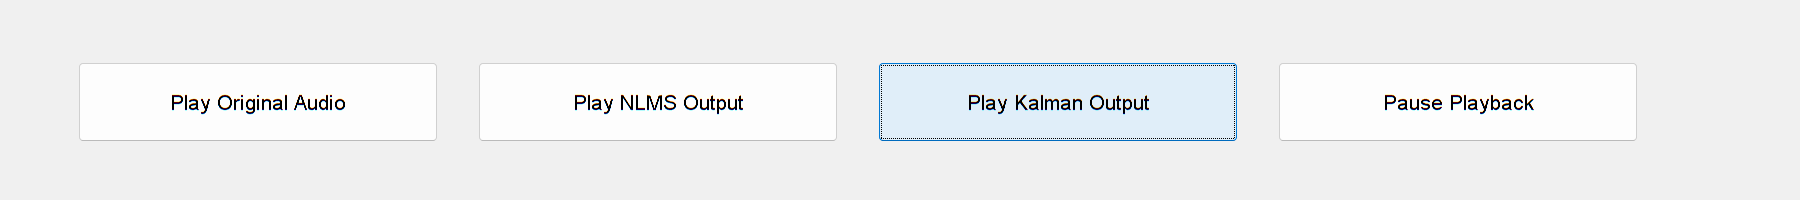





%% Playback UI
f_ui = figure('Name', 'Audio Playback Control', 'Position', [200, 200, 900, 100]);
bw = 180; bh = 40; bs = 20; sx = 40;

uicontrol('Style', 'pushbutton', 'String', 'Play Original Audio', ...
    'Position', [sx, 30, bw, bh], 'Callback', @(src,evt) sound(s_in, fs));
uicontrol('Style', 'pushbutton', 'String', 'Play NLMS Output', ...
    'Position', [sx + (bw+bs), 30, bw, bh], 'Callback', @(src,evt) sound(s_nlms, fs));
uicontrol('Style', 'pushbutton', 'String', 'Play Kalman Output', ...
    'Position', [sx + 2*(bw+bs), 30, bw, bh], 'Callback', @(src,evt) sound(s_kalman, fs));
uicontrol('Style', 'pushbutton', 'String', 'Pause Playback', ...
    'Position', [sx + 3*(bw+bs), 30, bw, bh], 'Callback', 'clear sound');


% %% Save Audio
% audiowrite('original.wav', s_in, fs);
% audiowrite('nlms_output.wav', s_nlms, fs);
% audiowrite('kalman_output.wav', s_kalman, fs);
% save('denoising_results_final.mat', 's_in', 's_ref', 's_nlms', 's_kalman', 'fs');
% fprintf('\nAll audio and data saved.\n');
